Przykład dla obiektu sterowania o transmitancji:


$$G_{O}(s) = \frac{s+1}{s(s^2 + s + 1)}$$


sterowanego za pomocą regulatora proporcjonalnego:


$$G_{R}(s) = K_{P}$$


Symboliczne zdefiniowanie transmitancji

syms kp real
syms Gr(s) Go(s)

Gr(s) = kp;
Go(s) = (s + 1) / (s^3 + s^2 + s);

Wyznaczenie transmitancji zastępczej:

Gopen(s) = Gr(s) * Go(s);
G(s) = simplify(Gopen(s) / (1 + Gopen(s)));
S(s) = simplify(1 / (1 + Gopen(s)));
Gu(s) = simplify(Gr(s) / (1 + Gopen(s)));

Sprawdzenie stabilności wynikających z kryterium Hurwitza:

[~ , den_closed] = numden(G) ;
[den_closed_coeffs, ~] = coeffs(den_closed, s);
den_closed_coeffs_array = den_closed_coeffs(s);

[H , delta] = hurwitz(den_closed_coeffs_array);

stable_k = solve(delta > 0, kp, ReturnConditions=true)

stable_k = struct with fields:
            kp: x
    parameters: x
    conditions: 0 < x


Transformacja uchybowa - wyznaczenie odpowiedzi transmitancji uchybowej na skok jednostkowy:

[num_e, den_e] = numden(S/s);

[num_e_coeffs, ~] = coeffs(num_e, s) ;
[den_e_coeffs, ~] = coeffs(den_e, s) ;

Wyznaczenie wielomianu $C(s)$:

syms c0 c1 c2
C(s) = c2*s^2 + c1*s + c0 ;
left = num_e(s)*num_e(-s) ;
left_coeffs = coeffs(left, s) ;
right = den_e(-s)*C(s) + den_e(s)*C(-s);
right_coeffs = coeffs(right, s) ;
conditions = [ ...
    left_coeffs(1) == right_coeffs(1); ...
    left_coeffs(2) == right_coeffs(2); ...
    left_coeffs(3) == right_coeffs(3)...
];
c_solved = solve(conditions, [c0, c1, c2])

c_solved = struct with fields:
    c0: 1/(2*kp)
    c1: (kp^2 - kp + 1)/(2*kp)
    c2: (kp^2 + 1)/(2*kp)


Wyznaczenie wskaźnika jakości $J_1$:

c_2 = c_solved.c2 ;
den_e_array = den_e_coeffs(s);
a3 = den_e_array(1);
J1 = c_2/a3

$$J1 = \frac{{\mathrm{kp}}^{2}+1}{2\,\mathrm{kp}}$$

Optymalizacja symboliczna

J1_dot = diff(J1, kp);
kp_opt = solve(J1_dot == 0, kp, ReturnConditions=true)

kp_opt = struct with fields:
            kp: [2×1 sym]
    parameters: [1×0 sym]
    conditions: [2×1 sym]



J1_val = [];
for i = 1:length(kp_opt.kp)
    if kp_opt.kp(i) > 0 % Z Hurwitza
        J1_val = [J1_val, double(subs(J1, {kp}, kp_opt.kp(i)))];
    else
        J1_val = [J1_val, NaN];
    end
end

[opt_val, opt_index] = min(J1_val);
fprintf("Optymalny regulator względem kryterium J1 ma postać Gr(s) = %d, i wynosi on J1 = %d", kp_opt.kp(opt_index), opt_val);

Optymalny regulator względem kryterium J1 ma postać Gr(s) = 1, i wynosi on J1 = 1

Optymalizacja numeryczna wskaźnika jakości:

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2    2.600000e+00    0.000e+00    3.800e-01
    1       4    2.384424e+00    0.000e+00    3.758e-01    4.510e-01
    2       6    1.387720e+00    0.000e+00    3.095e-01    2.199e+00
    3       9    1.013844e+00    0.000e+00    9.010e-02    1.169e+00
    4      12    1.000267e+00    0.000e+00    9.270e-02    2.037e-01
    5      14    1.000361e+00    0.000e+00    1.693e-02    5.006e-02
    6      16    1.000001e+00    0.000e+00    9.329e-04    2.567e-02
    7      18    1.000000e+00    0.000e+00    2.006e-04    1.409e-03
    8      20    1.000000e+00    0.000e+00    2.029e-06    1.438e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


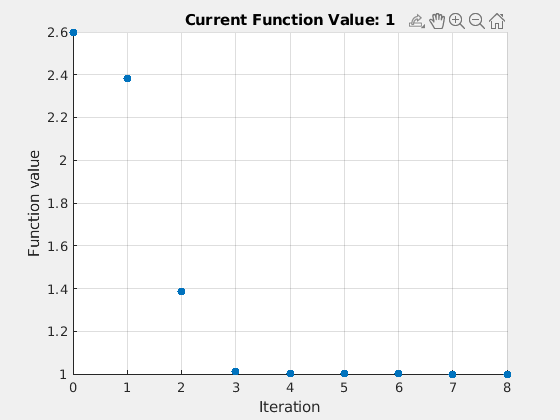

j_numeric_e = @(x)(double(subs(J1, {kp}, x))) ;
options = optimoptions("fmincon" , ...
    "Display", "iter" , ...
    "PlotFcn", @optimplotfval, ...
    "OptimalityTolerance", 1e-4 ...
);

x0 = [5];
A = [];
b = [];
Aeq = [];
beq = [];
lb = [0]; % Z Hurwitza
ub = [];
nonlcon = [];
x_opt_e = fmincon(j_numeric_e, x0, A, b, Aeq, beq, lb, ub, nonlcon, options);